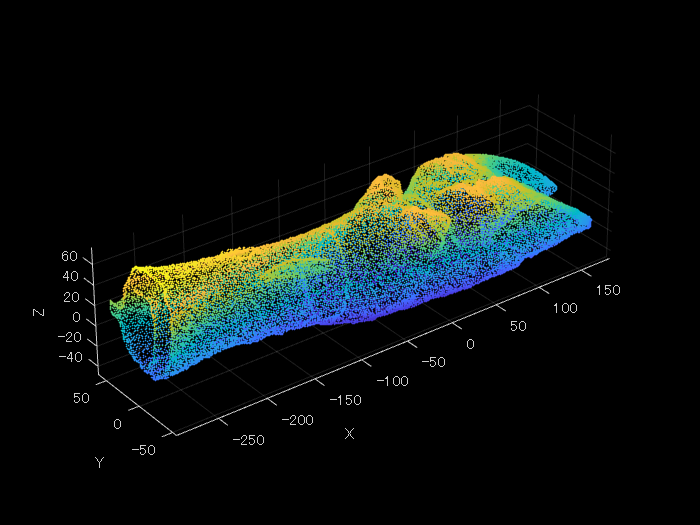

% file = uigetfile('.stl');
file = '..\3ddata\busako_RH_0000_remove.stl';
ptCloud = import3Dmodel(file, true);

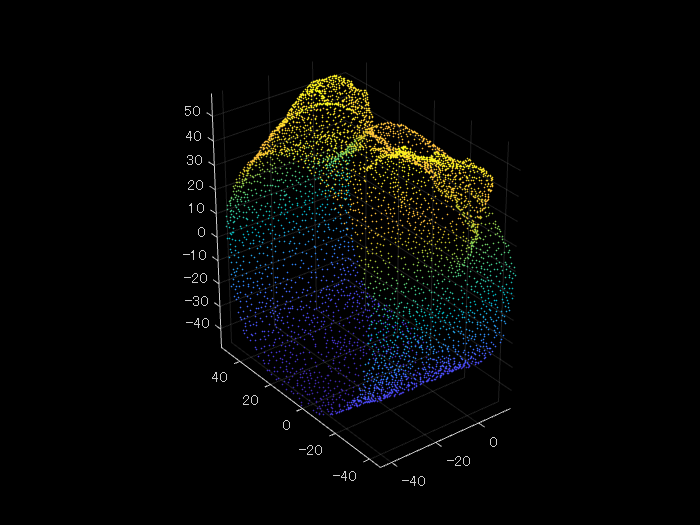

sp = ptCloud.Location;
t = 1.5;
% dt = -22;
axes = 'x';
roi_pt = sp(sp(:,1)>-45 & 15>sp(:,1), :);
r = pointCloud(roi_pt);
switch axes
    case 'x' % x軸方向にスライスしたい
        limit = r.XLimits;
        axisIdx = 1;
    case 'y'
        limit = r.YLimits;

        axisIdx = 2;
    case 'z'
        limit = r.ZLimits;
        axisIdx = 3;
end

pcshow(roi_pt, 'AxesVisibility', 'on')

n = 0;
thetas= [];
rhoes = [];
thetaPlus = [];
rhoPlus = [];
X = [];
Y = [];
dt = limit(1);
for i = limit(1):t:limit(2)
    dt = i + t;
    
    cross_section = roi_pt(roi_pt(:,axisIdx)>(dt-t) & (dt+t)>roi_pt(:,axisIdx), :);
%         Point = pointCloud(cross_section);

    switch axisIdx
        case 1
            cross = cross_section(:,[2 3]);
        case 2
            cross = cross_section(:,[1 3]);
        case 3
            cross = cross_section(:,[1 2]);
    end
    x = cross(:,1);
    y = cross(:,2);
    [thetaSorted, rhoSorted] = sortPointOnPolar([x y]);
    figure();
%     plot(thetaSorted, rhoSorted, '-');
%     daspect([1 1 1]);
    th_idx =  thetaSorted>=0;
    thOnlyPlus = thetaSorted(th_idx, :);
    rhOnlyPlus = rhoSorted(th_idx, :);
    thetaPlnew = thOnlyPlus + n*pi;
    TP = thetaPlus;
    thetaPlus = [TP;thetaPlnew];
    RP = rhoPlus;
    rhoPlus = [RP;rhOnlyPlus];

    thetanew = thetaSorted + (2*n+1)*pi;

    T = thetas; 
    thetas = [T;thetanew];
    R = rhoes;
    rhoes = [R;rhoSorted];
    n = n + 1;
    x = rhoSorted.*cos(thetaSorted);
    y = rhoSorted.*sin(thetaSorted);

%     figure("Name",num2str(dt));
% 
% %     plot(thetaSorted, rhoSorted, '-');
% %     plot(thetaSorted, x);
%     plot(thetaSorted, y);
end
r = max(rhoes);
t = 0:2*pi:(2*n+1)*pi;
t_plus = 0:pi:n*pi;

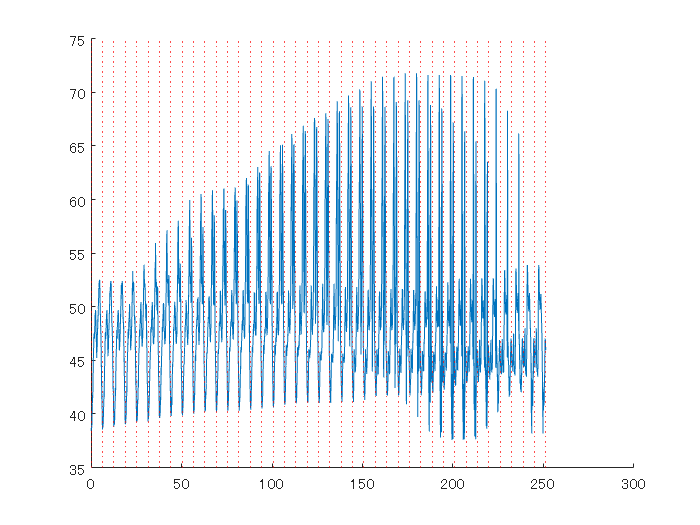

X = rhoes .* cos(thetas);
Y = rhoes .* sin(thetas);


figure("Name", "theta-rho_plot");
hold on;
plot(thetas, rhoes)
xline(t, ':r');
hold off

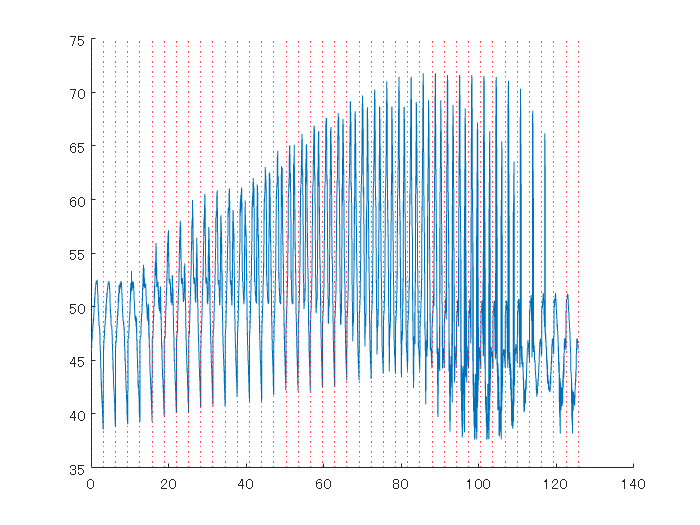

figure("Name","OnlyPlus thata-rho_plot");
xline(t_plus, ':r')
hold on;
plot(thetaPlus, rhoPlus);
hold off;

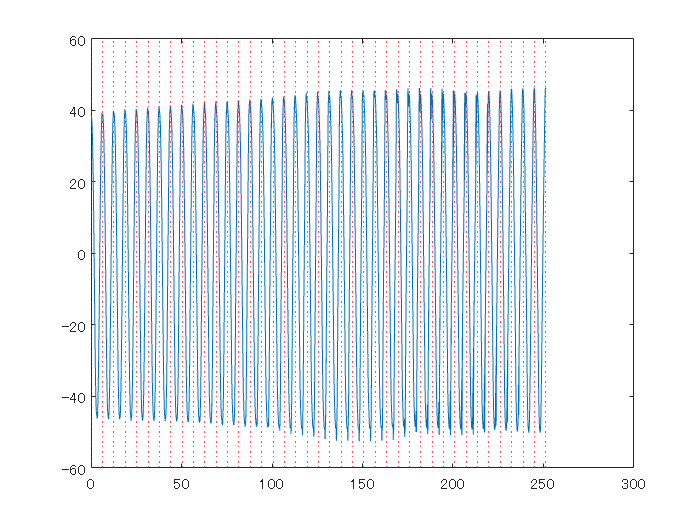

max(thetas);
figure("Name","cos")
plot(thetas, X);xline(t, ':r')

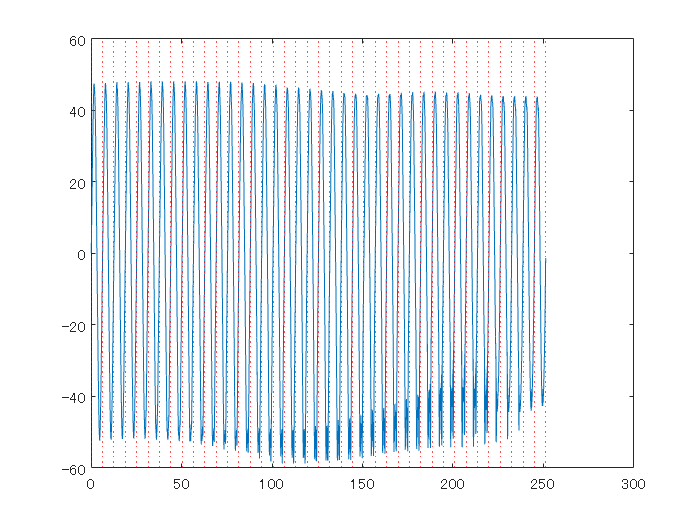

figure("Name","sin")
plot(thetas, Y);xline(t, ':r')

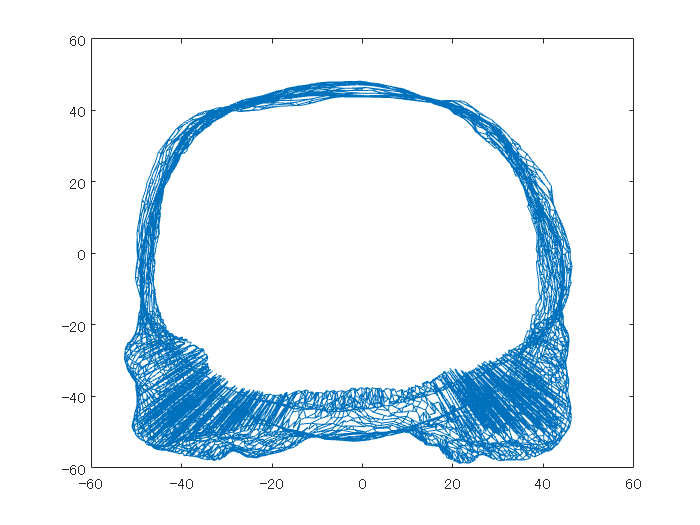

plot(X, Y);

% cross_sec = sp(sp(:,axisIdx)>(-9-t) & (-9+t)>sp(:,axisIdx), :);
sp = ptCloud.Location

sp = 1.0e+02 *

   1.121177002787590   0.598113201558590   0.246980898082256
   1.107343360781670   0.606889277696609   0.226921457797289
   1.104145422577858   0.593284070491791   0.267608799040318
   1.199018433690071   0.592128112912178   0.244445987045765
   1.216267347335815   0.593115128576756   0.234430506825447
   1.201445311307907   0.593516454100609   0.234795529395342
   1.224544346332550   0.538449920713902   0.316816233098507
   1.195853278040886   0.539022013545036   0.328312143683434
   1.218703091144562   0.533165596425533   0.325447730720043
   1.118161231279373   0.581490397453308   0.287860110402107


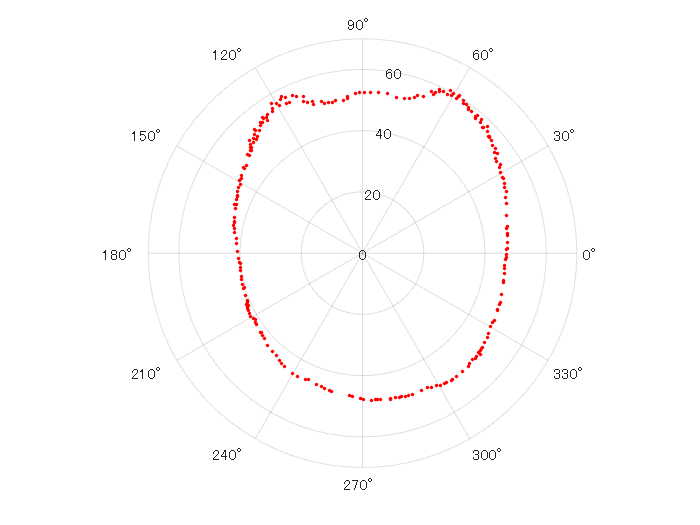

tw = 1.5;
at = "-30";
at_n = str2num(at);
index = sp(:,1) > at_n-tw & at_n+tw > sp(:,1);
OneDanmen = sp(index, :);
oneD = OneDanmen(:,[2 3]);
x = oneD(:,1);
y = oneD(:,2);

[th, rh] = sortPointOnPolar([x y]);% [theta, rho] = cart2pol(x,y);
figure;

polarplot(th, rh, '.r');

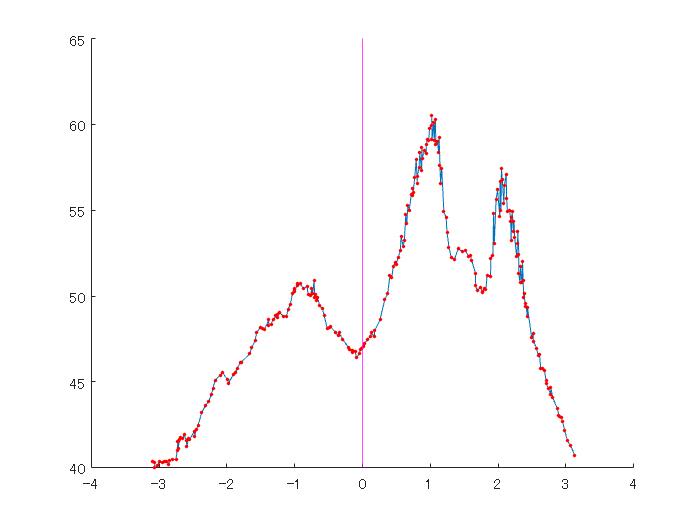

% polarplot(th, rh, '.r');
figure("Name","theta-rho_plot");
hold on;
plot(th, rh, '-');
plot(th, rh, '.r');
xline(0, 'm')
hold off;

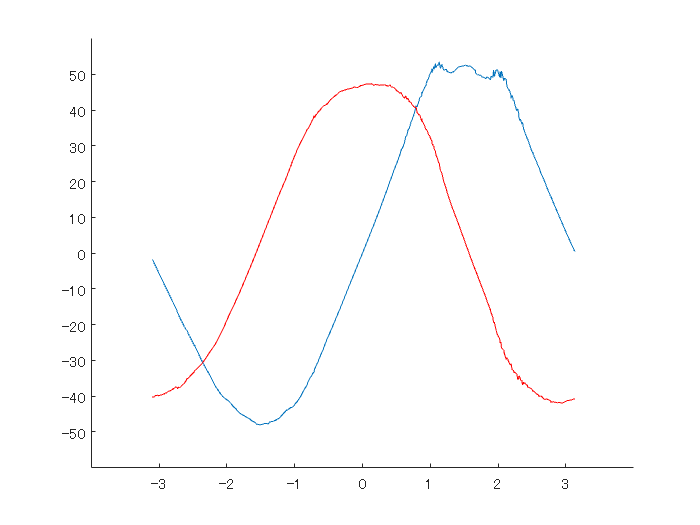

y_pro = rh.*sin(th);
figure;
hold on;
plot(th, y_pro, '-');
plot(th, rh.*cos(th), '-r');
hold off;